#  DC Motor Dynamics

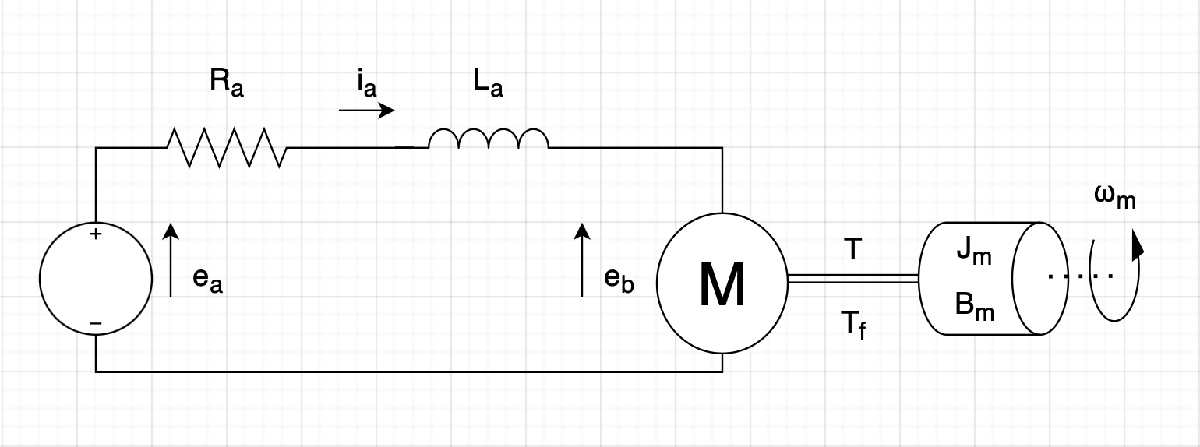

clear
Jm = 3.2284E-6;  % rotational inertia           [Nms^2/rad]
Bm = 3.5077E-6;   % vicous friction              [Nms/rad]
Kt = 0.0274;  % Motor Torque constant        []
Ke = 0.0274;  % Motor Back EMF constant      []
Ra = 4;     % armature resistance          [Ω]
La = 2.75E-6;   % armature inductance          [H]
gR = 12;
R = 3.5;
% Controller Parameters
Kp = 0.5;
Ki = 0.4;
Kd = 0;
%DC Motor Transfer Function
s = tf("s");
motor_tf = Kt/(s*((Jm*s+Bm)*(La*s+Ra)+(Kt*Ke)));
Ts = 1e-3;                               % Sample Time
dmotor_tf = c2d(motor_tf, Ts,'ZOH');     % Discreet TF of motor
Cntrl = pid(Kp,Ki,Kd);                   % PID Controler TF
dCntrl = c2d(Cntrl,Ts,'tustin');         % Discreet PID TF
sys_cl = feedback(dCntrl*dmotor_tf,1);   % Discreet System
dPlant = zpk(sys_cl)                     % Reagrange to Zero Pole Gain 


dPlant =
 
  0.00051965 (z-0.9992) (z+0.9831) (z+9.256e-07)
  ----------------------------------------------
       z (z-0.9992) (z^2 - 1.943z + 0.9438)
 
Sample time: 0.001 seconds
Discrete-time zero/pole/gain model.
Model Properties


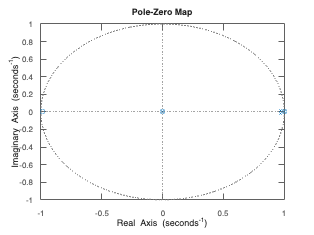

% Simulate the  response of the system 
pzmap(dPlant)

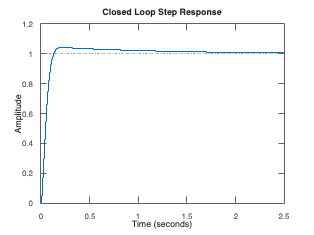

step(dPlant); title("Closed Loop Step Response")

[wn, zeta, poles_cl] = damp(dPlant);

% PID Tunner 
Cntrl = pidtune(dmotor_tf, 'PI')


Cntrl =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 0.4, Ki = 1.46, Ts = 0.005
 
Sample time: 0.005 seconds
Discrete-time PI controller in parallel form.
Model Properties


pidTuner(dmotor_tf,Cntrl)

% Sys Id Motor

% Retune PID